clear; close all;

# Design and compare different feedback controllers

% load previously designed model
load('chabo_ol_dynamics_disc.mat');

## identical design parameters

qPitch                  = 1;
qPitchVelocity          = 0;
qSpeed                  = 0;
qFlywheelVelocity       = 0.0001;
rTires                  = 1;
rFlywheel               = 1;
R                       = diag([rTires, rFlywheel]);

## controller 1

qPosition{1}            = 0.1;
Q{1}                    = diag([qPitch, qPitchVelocity, qPosition{1}, qSpeed, qFlywheelVelocity]);
Kd{1}                   = dlqr(chabo_ol_disc.A, chabo_ol_disc.B, Q{1}, R);

## controller 2

qPosition{2}            = 1;
Q{2}                    = diag([qPitch, qPitchVelocity, qPosition{2}, qSpeed, qFlywheelVelocity]);
Kd{2}                   = dlqr(chabo_ol_disc.A, chabo_ol_disc.B, Q{2}, R);

## controller 3

qPosition{3}            = 10;
Q{3}                    = diag([qPitch, qPitchVelocity, qPosition{3}, qSpeed, qFlywheelVelocity]);
Kd{3}                   = dlqr(chabo_ol_disc.A, chabo_ol_disc.B, Q{3}, R);

## simulate set-point stabilization maneuver

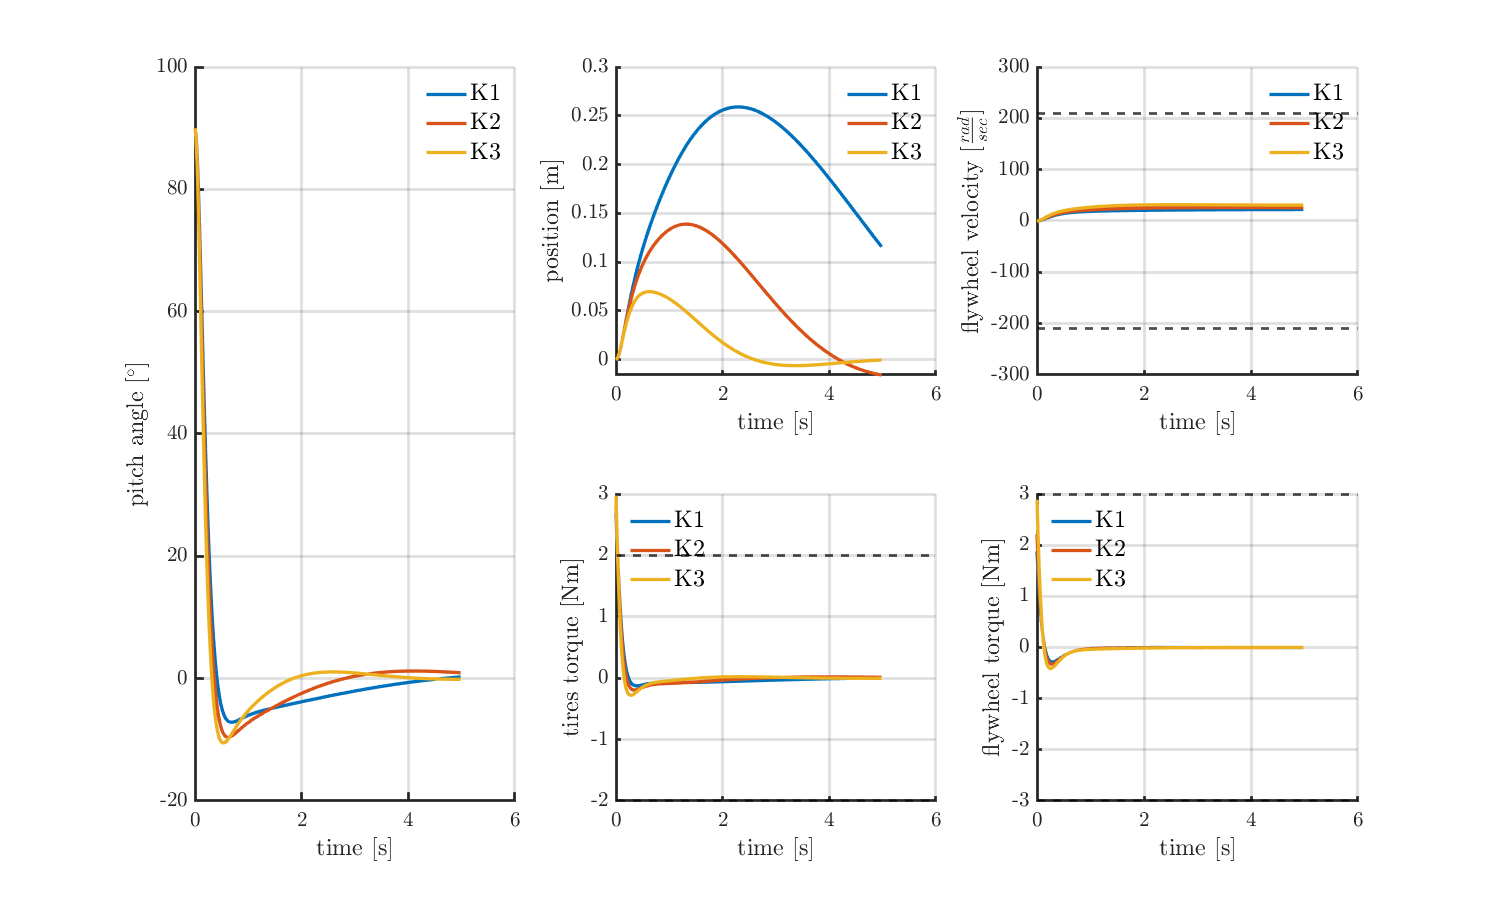

% initial conditions and simulation parameters
x0 = [deg2rad(90); 0; 0; 0; 0; 0];
N  = 250;
for i =1:3
    [X{i},U{i}]   = simChaboDynamics(Kd{i},x0,N);
end

plot_lqr_simulation_study(X,U,constraints);

## let's animate the movement

load('real_world.mat');

### controller 1

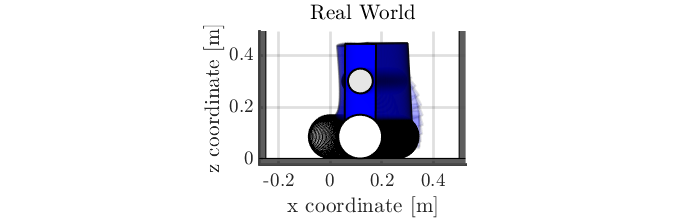

animate_movement_real_world(real_world,X{1}(:,1),X{1}(:,3));

### controller 2

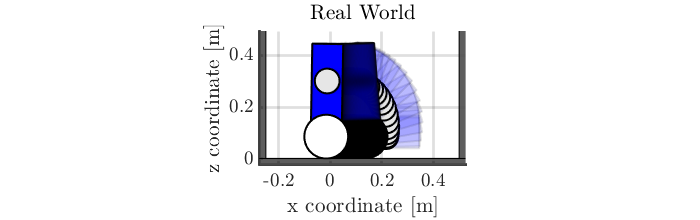

animate_movement_real_world(real_world,X{2}(:,1),X{2}(:,3));

### controller 3

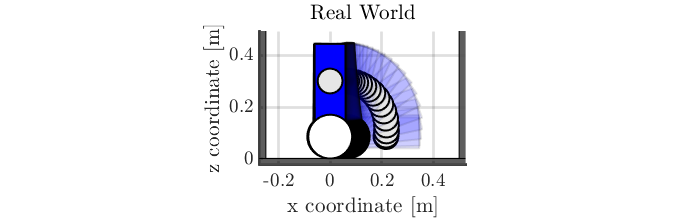

animate_movement_real_world(real_world,X{3}(:,1),X{3}(:,3));